% MATH 515
% Guided Lab 4
% Andrew Hutsell

% Exercise 1
function [t, w] = rk4(f, a, b, alpha, N)

    h = (b - a) / N;
    t = linspace(a, b, N+1);
    m = length(alpha);
    
    w = zeros(m, N+1);
    w(:,1) = alpha(:);
    
    for i = 1:N
        ti = t(i);
        wi = w(:,i);
        
        k1 = h * f(ti, wi);
        k2 = h * f(ti + h/2, wi + k1/2);
        k3 = h * f(ti + h/2, wi + k2/2);
        k4 = h * f(ti + h,   wi + k3);
        
        w(:,i+1) = wi + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
    end
end


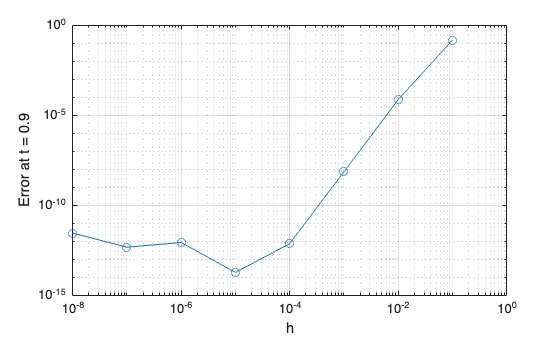

% Exercise 2

% Part b
f = @(t,y) 1 - y + exp(2*t)*y.^2;
exact = @(t) exp(-t).*tan(exp(t)-1);

h = 0.1;
a = 0;
b = 0.9;
alpha = 0;

N = (b-a)/h;
[t_2,w_2] = rk4(f, a, b, alpha, N);

x_2 = exact(t_2);
err_2 = abs(x_2 - w_2);

% Part c

% Range from 10^-8 to 10^-1
h = logspace(-8, -1, 8);

Nvals = (b-a)./h;

errors = zeros(size(Nvals));
hs = zeros(size(Nvals));

for i = 1:length(Nvals)
    N = round(Nvals(i));
    
    h = (b - a)/N;
    hs(i) = h;
    
    [t, w] = rk4(f, a, b, alpha, N);
    
    w_final = w(:,end);
    errors(i) = abs(exact(b) - w_final);
end

% Log-log plot
figure
loglog(hs, errors, 'o-')
xlabel('h')
ylabel('Error at t = 0.9')
grid on



order = zeros(length(errors)-1, 1);

for i = 1:length(errors)-1
    order(i) = log(errors(i)/errors(i+1)) / log(hs(i)/hs(i+1));
end

disp('Estimated orders between successive points:')

Estimated orders between successive points:


disp(order)

   -0.7884
    0.2608
   -1.6604
    1.5951
    3.9996
    4.0125
    3.3118



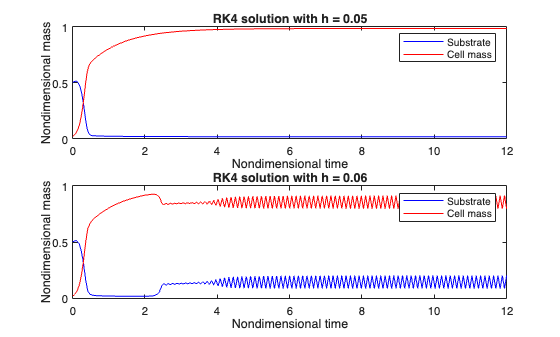

% Exercise 3

m = 16;
a = 0.25;

f = @(t, y) [1 - y(1) - (m * y(1) * y(2)) / (a + y(1));
    (m * y(1) * y(2)) / (a + y(1)) - y(2)];

t0 = 0;
tf = 12;
h_b = 0.05;
N = (tf - t0)/h_b;
alpha = [0.5; 0.02];


[t, w] = rk4(f, t0, tf, alpha, N);
s = w(1,:);
x = w(2,:);


subplot(2,1,1);
% Plot
plot(t, s, 'b', t, x, 'r')
legend('Substrate', 'Cell mass')
xlabel('Nondimensional time')
ylabel('Nondimensional mass')
title(['RK4 solution with h = ', num2str(h_b)])



h_c = 0.06;
N = (tf - t0)/h_c;
[t, w] = rk4(f, t0, tf, alpha, N);
s = w(1,:);
x = w(2,:);


subplot(2,1,2);
% Plot
plot(t, s, 'b', t, x, 'r')
legend('Substrate', 'Cell mass')
xlabel('Nondimensional time')
ylabel('Nondimensional mass')
title(['RK4 solution with h = ', num2str(h_c)])

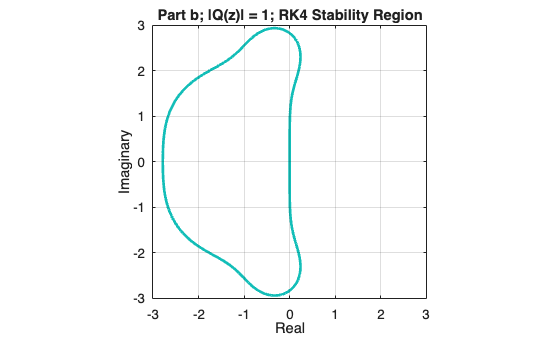

% Exercise 4

% Part b
clear; clc; close all;
x = linspace(-3, 3, 301);
y = linspace(-3, 3, 301);
[X, Y] = meshgrid(x, y);
Z = X + 1i*Y;

Q = 1 + Z + (Z.^2)/2 + (Z.^3)/6 + (Z.^4)/24;

contour(X, Y, abs(Q), [1 1], 'LineWidth', 2);
xlabel('Real');
ylabel('Imaginary');
title('Part b; |Q(z)| = 1; RK4 Stability Region');
grid on;
axis equal;

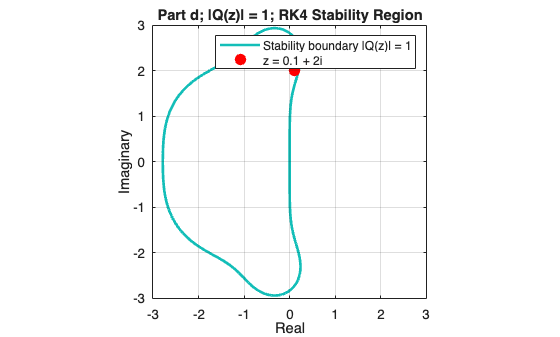




% Part d
x = linspace(-3, 3, 301);
y = linspace(-3, 3, 301);
[X, Y] = meshgrid(x, y);
Z = X + 1i*Y;

Q = 1 + Z + (Z.^2)/2 + (Z.^3)/6 + (Z.^4)/24;

figure;
contour(X, Y, abs(Q), [1 1], 'LineWidth', 2);
hold on;

% Plot specific point
lambda = 1 + 20i;
h = 0.1;
z = h * lambda;

plot(real(z), imag(z), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

xlabel('Real');
ylabel('Imaginary');
title('Part d; |Q(z)| = 1; RK4 Stability Region');
grid on;
axis equal;
legend('Stability boundary |Q(z)| = 1', 'z = 0.1 + 2i');




f = @(t, y) (1 + 20i)*y;
a = 0;
b = 10;
alpha = 1;
h = 0.1;
N = (b - a)/h;

[t, w] = rk4(f, a, b, alpha, N);
figure;
plot(t, w, 'LineWidth', 2);

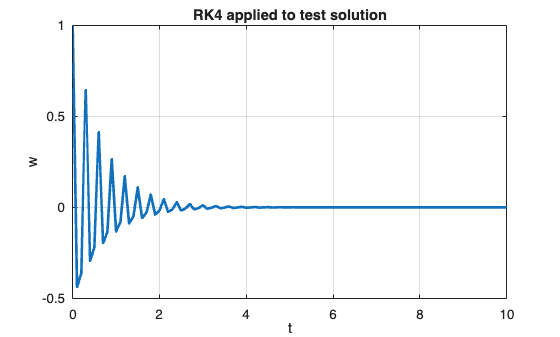

xlabel('t');
ylabel('w');
title('RK4 applied to test solution');
grid on;